# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0175   -0.0313   -0.0582   -0.0087   -0.0250   -0.0186   -0.0195   -0.0183   -0.0175   -0.0174   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175   -0.0175
    0.0512   -0.0384    0.0493    0.0380    0.0553    0.0502    0.0528    0.0505    0.0511    0.0514    0.0512    0.0513    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0.0512    0

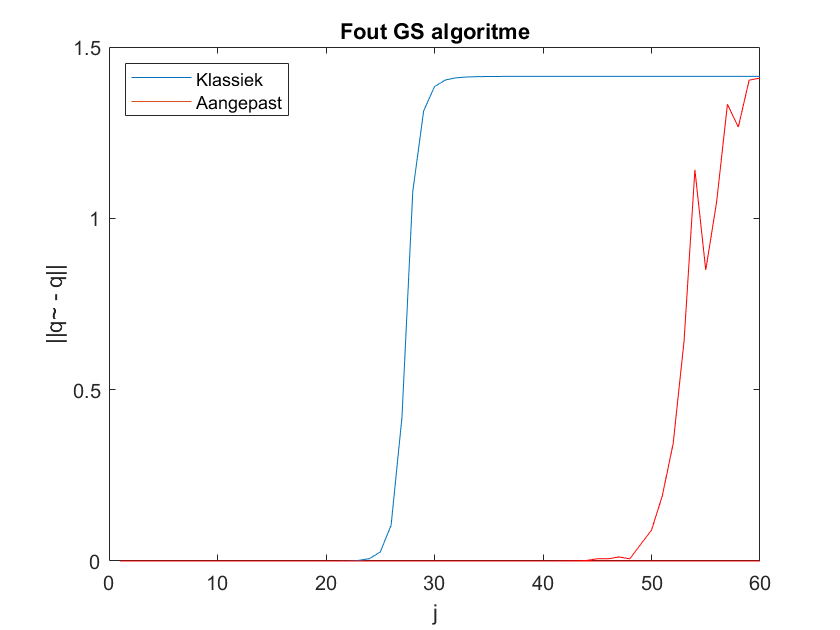


% Oefening 4
e1 = zeros(n);
e2 = zeros(n);

[Q1,~] = klGS(A);
[Q2,~] = modGS(A);

for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
    e2(j) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest') % fout is exponentieel ma geen idee waarom

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0794   -0.0622   -0.0892
   -0.0992   -0.1151   -0.1196
    0.0932    0.0834    0.0795
    0.0844    0.0403    0.0753
    0.0197    0.0083   -0.0041
    0.0045    0.0227    0.0027
   -0.0828   -0.0083   -0.1251
    0.0680    0.1463    0.0460
    0.0331    0.0386    0.0359
    0.0257    0.0686    0.0512


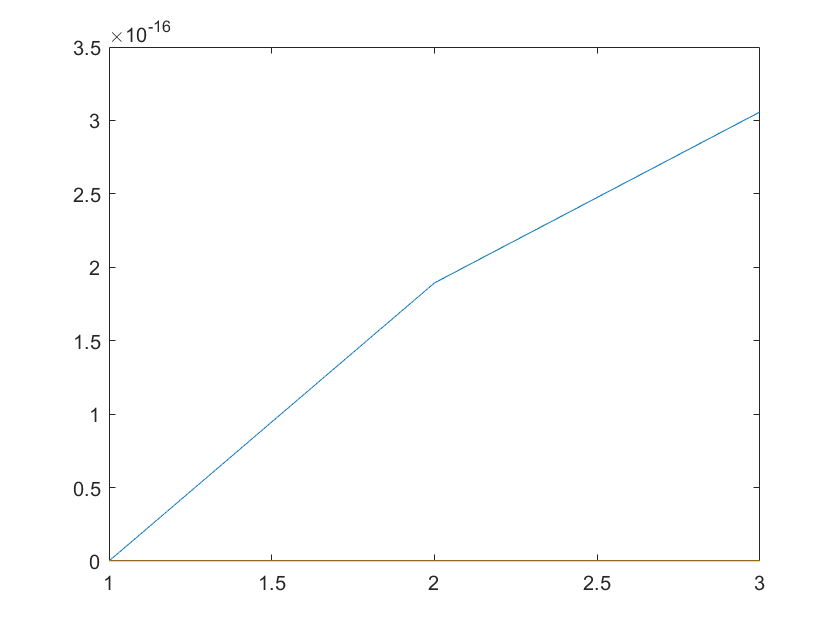


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

% Oefening 9
m = 200;
n = 50;
k = 5;

B = randn(m,n);
[Q,~] = qr(B,0)

Q =    -0.0109   -0.0327   -0.0952   -0.0201   -0.0732   -0.0161   -0.0235    0.0587   -0.1140   -0.0570   -0.0368   -0.0265   -0.0588    0.0816   -0.0110   -0.0096   -0.0445   -0.0975   -0.0344    0.0712   -0.0275   -0.0445   -0.0133    0.0334   -0.0969   -0.0035   -0.0814   -0.0878   -0.0387   -0.0077   -0.0557    0.0790   -0.0281    0.0516   -0.0100    0.0549    0.0177   -0.0470    0.0471   -0.0112   -0.0823   -0.0260   -0.0035   -0.0327   -0.0859   -0.0854   -0.1324    0.1148   -0.0687    0.0182
    0.1146   -0.0483   -0.0352   -0.1161   -0.0279    0.0553    0.1393    0.0408   -0.0113   -0.0224   -0.0275   -0.0166    0.0679    0.1302   -0.1695    0.0028   -0.1310   -0.0181    0.0356    0.0057    0.0628    0.0118    0.0235   -0.0353   -0.0065    0.0539    0.1452   -0.0340   -0.0538   -0.0332    0.0181   -0.1195   -0.0057   -0.0846   -0.1412    0.1809   -0.0043    0.0620    0.0010    0.0024    0.1684   -0.0373    0.0203   -0.0868    0.0376    0.0264    0.0335    0.0092   -0.0103    0


V = randn(n) % change this to orthogonal matrix

V =    -0.6902   -0.0660    2.3627   -0.9767    0.0267   -0.1493   -1.5741   -0.4399   -0.1467    0.3728    3.5192   -0.1746    2.3849   -1.5021   -0.7730   -0.3225   -0.5233   -1.2216    0.6103   -0.7302   -1.9032   -1.5535    0.0254    0.0351    0.0444   -0.3474    1.3525   -1.3295   -0.8354   -0.4703   -0.3580   -1.8783   -1.1950   -0.3897    1.1494    0.8309   -1.5537   -0.4920   -0.9564    1.0292   -1.2187    0.4044    0.2025   -1.6541    0.9010   -0.3261    0.2924   -0.2818   -0.0278    1.7353
   -0.7409    0.5840   -0.7343    0.7271    0.1888   -0.6112   -1.1398    0.8022    0.1687    1.4082    1.0332    1.1103    1.3684   -1.1072   -0.5821   -0.0452    0.7446   -0.8583   -0.1848    0.1514    2.4991   -0.8411   -0.5690   -1.7657    0.1960   -0.8267   -0.2703    1.6308   -0.2667    1.2978   -0.8558   -0.3904   -1.9498   -0.9487    0.6917   -0.4792    1.8650   -1.2558    0.5765   -0.6613    0.4937   -0.3297   -1.3276   -1.3005   -0.0757    1.0436   -1.0933    0.8329    1.2043   -0


D = diag(2.^linspace(0,k,n)) % linspace returns n evenly spaced values between 0 and k

D =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0733         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     


A = Q*D*V

A =    -8.6957    5.5429    7.5192   -5.1571   -3.1413    0.7450   -2.7387   -8.2685    4.5978    1.0417   -3.1806   -1.3913    1.3233    8.6061    4.5844   13.3010    1.2516   -2.9124    8.0436    2.3368   -2.2832   -7.0715   -1.6862    1.6100    8.7894    5.9041   -2.4441    8.9271   -4.1562    0.2858    3.4280    4.8609    3.0135   -1.2948    1.5602   -0.0877   -6.9590   -0.6165   -8.2141   11.3895   12.1700   -4.9920   -2.0844    0.1185    5.9836   -6.2688   -0.0192  -12.5314  -16.6048    2.8668
   -4.5547    0.4935    1.2081    3.5411   -3.2270   -4.7482    3.5785    3.0312    3.2672   -4.5759    7.5987   -1.8084   -0.5333   -8.2360    2.1940    0.5750    4.1939    0.2594    9.0140   -7.1607    5.3250    2.1429    1.2295   -3.5770   -5.0576  -11.3168   -5.6536   -1.3104  -11.2747   -1.8064   -4.8602   -0.2938   -3.0341   -1.5153    4.6185    4.6820    3.5735    9.6638   -0.5824    0.1826   -2.5752    1.3575   -1.4591   -1.4031   -2.6841   -0.5085    1.4336    5.7479   15.5932    1


K = D(1, 1)/D(n, n)

K = 0.0313


[U,S,V_orth] = svd(A)

U =    -0.0966   -0.0199   -0.0202    0.0931   -0.0239   -0.0270   -0.1807   -0.0012   -0.0208    0.1015   -0.0523   -0.0561    0.0286   -0.0495   -0.0618    0.0306   -0.0555    0.0042    0.0364   -0.0162    0.0382   -0.0177   -0.0544    0.0310    0.0412    0.0365   -0.0237   -0.0670   -0.0513    0.0539   -0.1015   -0.0370   -0.0224    0.0094    0.1202   -0.0513    0.0322    0.0634    0.0973    0.0523   -0.0587    0.0160    0.0483    0.1067    0.0657    0.0172   -0.0216   -0.0144    0.0581    0.0406
    0.0173   -0.0249   -0.0051   -0.0952   -0.0967    0.0576    0.0040   -0.0517   -0.0450   -0.1374    0.0189    0.0368   -0.0527    0.0884   -0.0743    0.0571   -0.0804   -0.0068    0.0539   -0.1507   -0.0097    0.0362    0.0589    0.0553   -0.1237    0.0601   -0.0378   -0.0167    0.0116   -0.0135   -0.0995   -0.2215    0.1396   -0.0208   -0.0825   -0.0083    0.1112   -0.0212   -0.0414    0.0725    0.0399    0.0563   -0.1226    0.0806    0.0002    0.0364    0.0721   -0.0555   -0.0014    0

S =   245.7511         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0  209.5251         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V_orth =     0.0331    0.0465    0.1743   -0.0361    0.0045   -0.2571    0.1993   -0.0642    0.0770   -0.0345    0.0355   -0.1284    0.0276   -0.0972    0.0900   -0.1382    0.1047   -0.1750    0.0416    0.0149   -0.1875    0.0970    0.1458   -0.1501   -0.0457   -0.4821    0.1485    0.0898    0.0495   -0.2516   -0.0912   -0.1071    0.0066    0.0217    0.1457    0.0886    0.0022    0.0661    0.2075    0.0278   -0.1395   -0.2758   -0.0053   -0.1069   -0.0265   -0.1226   -0.0333   -0.0406   -0.3132   -0.0970
   -0.0898   -0.1665   -0.0545    0.0911    0.0245   -0.1980   -0.0689   -0.2300   -0.0389   -0.1298   -0.2467    0.2876    0.2683    0.1188    0.0185    0.0777   -0.0947    0.0179   -0.0702    0.1241    0.0487    0.0145    0.1804   -0.1406    0.1084   -0.0360   -0.0814   -0.1765   -0.0101   -0.0614    0.1658   -0.1212    0.1766    0.1792   -0.1951    0.1747   -0.1633    0.2559    0.0783   -0.0709   -0.1583    0.1380   -0.0777    0.0937   -0.1433    0.2939   -0.0015    0.0063   -0.1358


K_2 = S(1, 1)/S(n, n)

K_2 = 616.7061


K_3 = norm(A) * norm(pinv(A))

K_3 = 616.7061


K_4 = norm(A) * norm((A.'*A)^(-1)*A.')

K_4 = 616.7061


K_5 = K^(-1)

K_5 = 32


% Oefening 10



# Opgave 2: Iteratieve methoden

A = sprand(1000,1000,10);
n = length(A);
m = 100;
v = rand(n,1);

[V,H] = Arnoldi(A,v,m);

Unrecognized function or variable 'Arnoldi'.